# Globals

clear
t_final = 25;
delta_t = 0.01;
t = 0:delta_t:t_final;

# Signal 1: Chirp

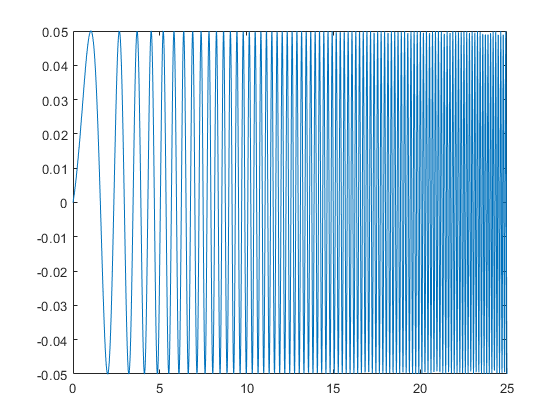

scale = 0.05;
f_start = 0.1;
f_end = 7;
chirp = scale*chirp(t,f_start,t(end),f_end,'linear',-90);
plot(t,chirp)

# Signal 2: SoS

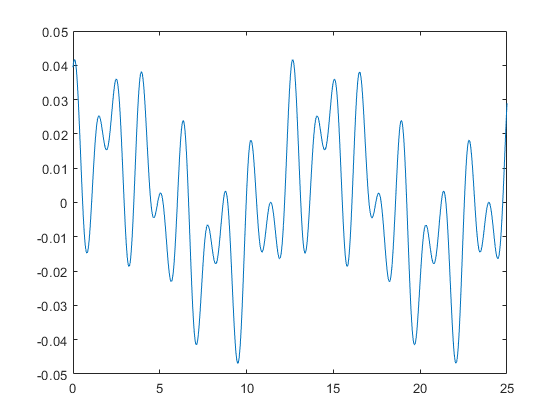

f = [0.5 3 5];
p = [pi/6 pi/2 pi/3];
scale = .05/3;
syms f1 f2 f3 p1 p2 p3
for i = 1:size(t,2)
    sos(i) = scale*(sin(f(1)*t(i)+p(1))+sin(f(2)*t(i)+p(2))+sin(f(3)*t(i)+p(3)));
end
plot(t,sos)

# Plant

%Plant model of yaw dynamics 
%From (Elzinga, M. J., Dickson, W. B., & Dickinson, M. H. (2012).
%The influence of sensory delay on the yaw dynamics of a flapping insect.
%Journal of the Royal Society Interface, 9(72), 1685–1696.
%https://doi.org/10.1098/rsif.2011.0699)
Cu = 3.53e3;
Cw = 7.47e2;
I = 1.97e3;
G_plant = tf(Cu,[I Cw]); %Torque to Velocity

# Closed Loop Transfer Function

%PI controller
Kp = 20;
Ki = 20;

C_tf = tf([Kp Ki],[1 0])

C_tf =
 
  20 s + 20
  ---------
      s
 
Continuous-time transfer function.



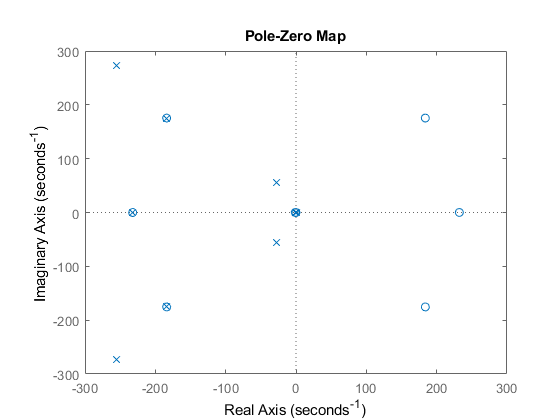


%Delay (Pade approximation)
sym s;
td =.02;
s = tf('s');
[nump,denp]=pade(td,3);
d_tf = tf(nump,denp);

%Closed Loop Transfer Function
num = C_tf*G_plant*d_tf;
oltf = minreal(num);
den = (1 + oltf);
cl_tf = num/den;
figure
pzmap(cl_tf);

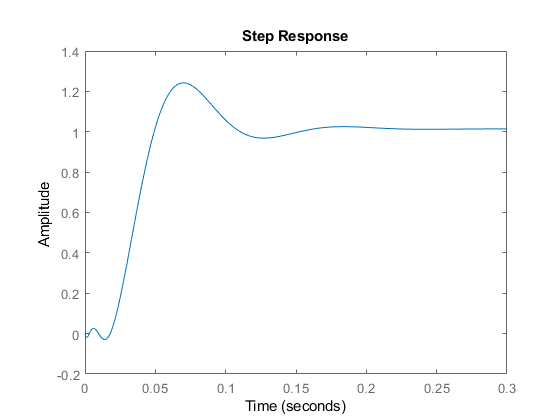

figure
step(cl_tf);

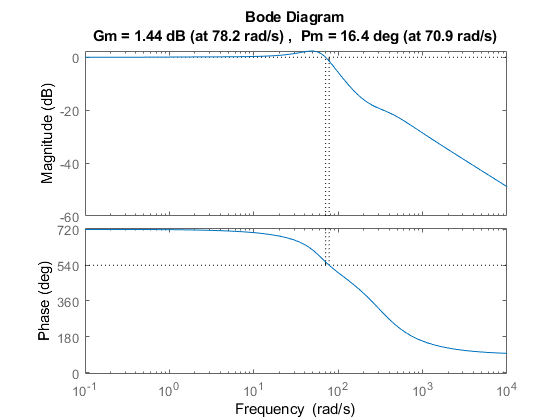

figure
margin(cl_tf)

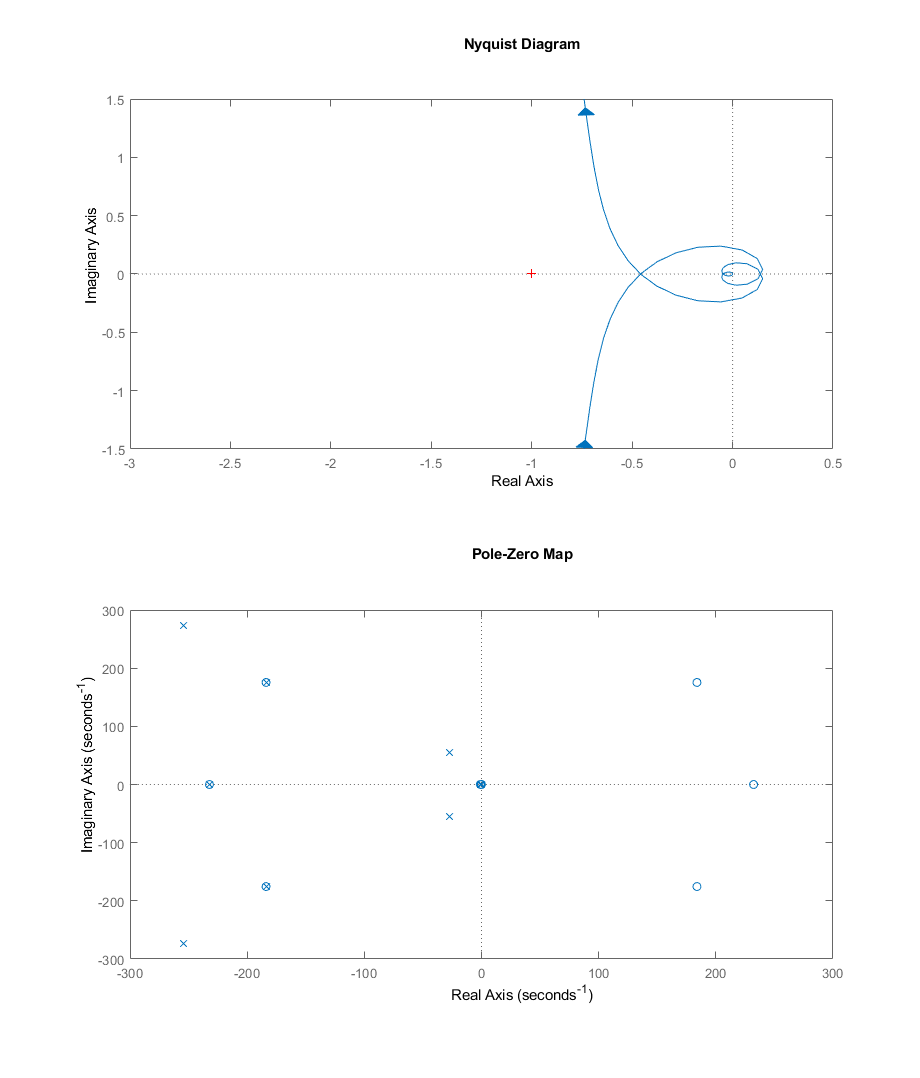

figure1=figure('Position', [100, 100, 1024, 1200]);
subplot(2,1,1)
h = nyquistplot(oltf);
p = getoptions(h);
p.XLim = {[-3, 0.5]};
p.YLim = {[-1.5, 1.5]};
setoptions(h,p);
subplot(2,1,2)
pzmap(cl_tf);

# Simulation and Plots

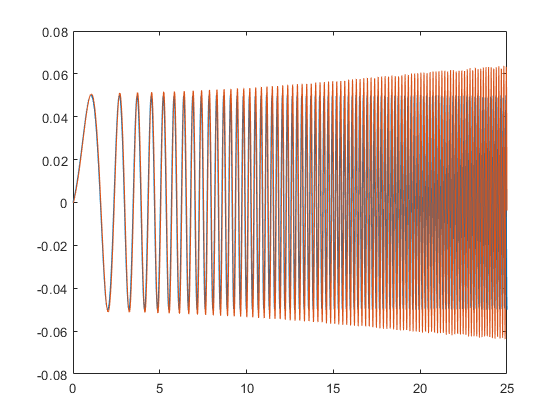

chirpsim = lsim(cl_tf,chirp,t);
sossim = lsim(cl_tf,sos,t);

figure
plot(t,chirp,t,chirpsim)

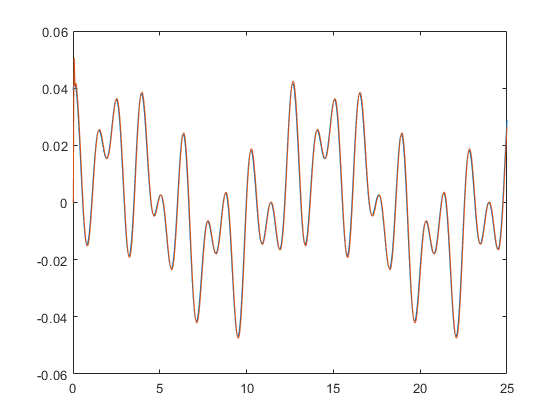

figure
plot(t,sos,t,sossim)

# Error Calculations

chirperror = sum((chirp-chirpsim').^2)

chirperror = 2.2818

soserror = sum((sos-sossim').^2)

soserror = 0.0149